A=[0 1 0 0 0 0 0
   0 0 1 0 0 0 0
   0 0 0 0 0 0 0
   0 0 0 0 7 0 0
   0 0 0 -7 0 0 0
   0 0 0 0 0 0 2
   0 0 0 0 0 -2 0]

A =      0     1     0     0     0     0     0
     0     0     1     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     7     0     0
     0     0     0    -7     0     0     0
     0     0     0     0     0     0     2
     0     0     0     0     0    -2     0


B=zeros(7)

B =      0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0


% C=[1
%     0 
%     1 
%     0]
D=zeros(7)

D =      0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0



syms t real;

exp_a = expm(A*(t));
exp_a_simplify = simplify(exp_a);
AA=exp_a_simplify

$$AA = \left(\begin{array}{ccccccc} 1 & t & \frac{t^{2}}{2} & 0 & 0 & 0 & 0\\ 0 & 1 & t & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & \cos\left(7\,t\right) & \sin\left(7\,t\right) & 0 & 0\\ 0 & 0 & 0 & -\sin\left(7\,t\right) & \cos\left(7\,t\right) & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & \cos\left(2\,t\right) & \sin\left(2\,t\right)\\ 0 & 0 & 0 & 0 & 0 & -\sin\left(2\,t\right) & \cos\left(2\,t\right) \end{array}\right)$$

xsv=[2 0 0 0 8 0 3]*exp_a_simplify

$$xsv = \left(\begin{array}{ccccccc} 2 & 2\,t & t^{2} & -8\,\sin\left(7\,t\right) & 8\,\cos\left(7\,t\right) & -3\,\sin\left(2\,t\right) & 3\,\cos\left(2\,t\right) \end{array}\right)$$

a=[2 0 0 0 8 0 3]*exp_a_simplify*[
    0 
    0
    1
    -1
    0 
    0 
    -1]

$$a = 8\,\sin\left(7\,t\right)-3\,\cos\left(2\,t\right)+t^{2}$$

syms t;
y = t^2+8*sin(7*t) - 3*cos(2*t)

$$y = 8\,\sin\left(7\,t\right)-3\,\cos\left(2\,t\right)+t^{2}$$

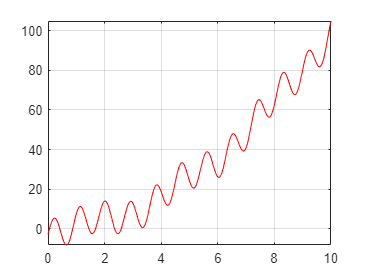

fplot(y,[0,10])
grid on
hold on
plot(out.stat.Time, out.stat.Data, 'red')


$$\left\lbrack \begin{array}{c}
1\\
0\\
1\\
0
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{cccc}
1 & 0 & 1 & 0
\end{array}\right\rbrack$$
